# Integrating ROS and Matlab

We will be running a ROS server on the rover's NUC which will manage all sense acquisition in parallel. This allows us to simply use Matlab code to quickly read sense data from the ROS channels when it is needed and we end up spending much less time executing slow Matlab sense code with more time for thinking!

#### Step 1 is to install the Matlab ROS toolbox

- **You may have to run this line to use the ROS toolbox:**

- `    pyenv("Version", "<path-to-python-3.9>");`

## Initialize ROS connection to NUC

clear
rosshutdown % Clear any existing ROS connection
% Initialize ROS connection

ROS_URI = 'http://192.168.34.152:11311/';
nuc_ip = '192.168.34.152';
rosinit(ROS_URI)

Initializing global node /matlab_global_node_50510 with NodeURI http://Ben-Grant-2.local:51787/ and MasterURI http://192.168.34.152:11311/.


% List all topics on the ROS network
% Topics are named buses over which nodes exchange messages.
rostopic list

/diagnostics                    
/laser_status                   
/rosout                         
/rosout_agg                     
/scan                           
/tf                             
/urg_node/parameter_descriptions
/urg_node/parameter_updates     


% setup usb camera ROS subsscriber
cam = rossubscriber("/usb_cam/image_raw/compressed", "DataFormat", "struct")

cam =   Subscriber with properties:

        TopicName: '/usb_cam/image_raw/compressed'
    LatestMessage: []
      MessageType: 'sensor_msgs/CompressedImage'
       BufferSize: 1
    NewMessageFcn: []
       DataFormat: 'struct'


img = receive(cam, 10)

Error using ros.Subscriber/receive
The function did not receive any data and timed out.

% get info for a ROS topic
rostopic info /diagnostics

Type: diagnostic_msgs/DiagnosticArray
 
Publishers:
* /urg_node (http://funroboteam1-nuc:38063/)
 
Subscribers:
* /matlab_global_node_76789 (http://Ben-Grant-2.local:51172/)


diag = rossubscriber("/diagnostics","DataFormat","struct");
msg = receive(diag, 10)

Error using ros.Subscriber/receive
The function did not receive any data and timed out.

rostopic info /scan

Type: sensor_msgs/LaserScan
 
Publishers:
* /urg_node (http://funroboteam1-nuc:42375/)
 
Subscribers:
* /rviz_1649985828749362117 (http://funroboteam1-nuc:33645/)
* /matlab_global_node_52969 (http://Ben-Grant-2.local:51578/)
* /matlab_global_node_67900 (http://funroboteam1-nuc:34749/)


laser = rossubscriber("/scan","DataFormat","struct");

scandata = receive(laser,1)

scandata = struct with fields:
       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 struct]
          AngleMin: -2.0923
          AngleMax: 2.0923
    AngleIncrement: 0.0061
     TimeIncrement: 9.7656e-05
          ScanTime: 0.1000
          RangeMin: 0.0200
          RangeMax: 5.6000
            Ranges: [683×1 single]
       Intensities: []


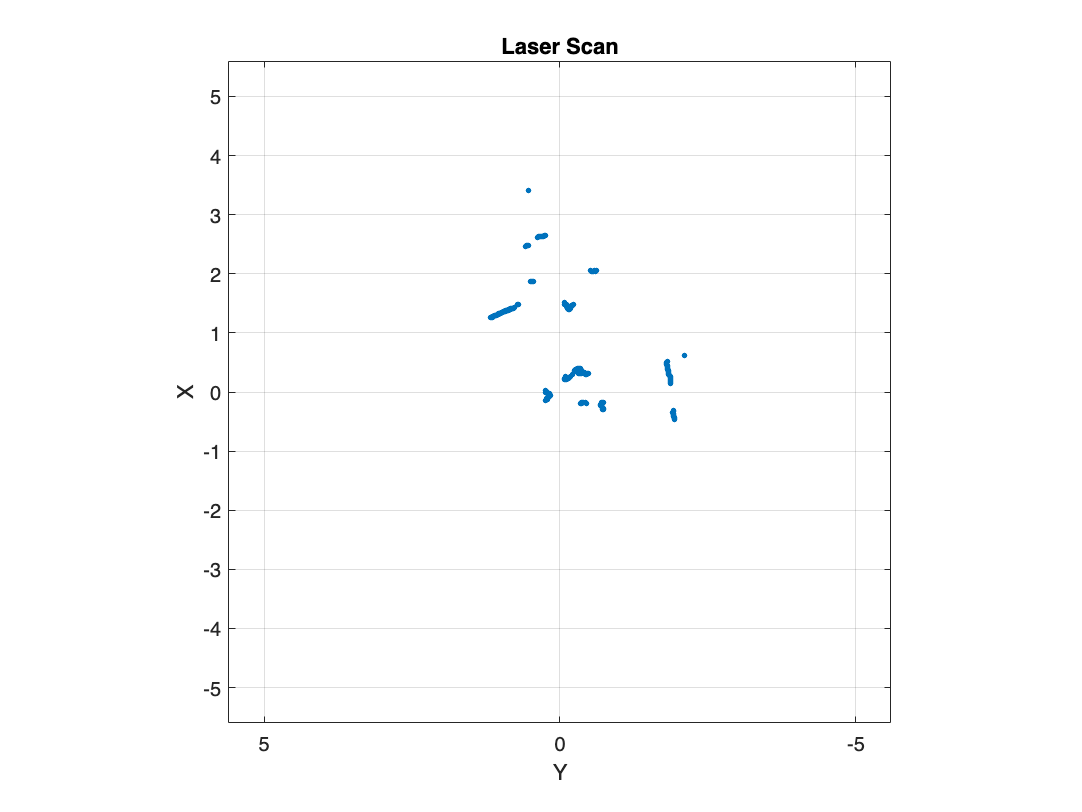

rosPlot(scandata)